# FEM2D: Thermal convection problems using Quadrilateral Elements

Taken from Toni Susin's blog  'Numerical Factory', [practice P2.12 ](https://numfactory.upc.edu/numfactory/subjects/FEM/FEM/practices/P2.11b/html/P2_11b_FEM2DAletaThermalQuadConvection_en.html)

## Engine cooling fin: State the problem

Consider the mesh file **meshAleta2DQuad.m** which represents half of the geometry of the cooling fin shown at the figure with the Bondary Conditions stated there.

Take the material conductivity coefficient kc=0.5 and no internal heat source (f=0).

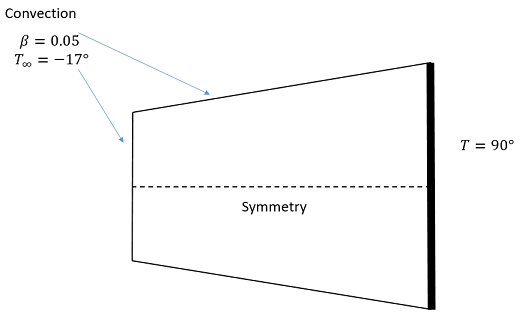

**Question**: Find the temperature at the point P=[0.9,2.1].

clearvars
close all

kc= 0.5;         %Thermal conductivity
ff= 0.0;
tempRight= 90.0; %Temperature at the right boundary
beta= 0.05;      %Convection at top, bottom and left boundaries
Tinf=-17.0; 
p=[0.9,2.1];     %Point to interpolate the temperature      


Load geometry: node coordinates and elements

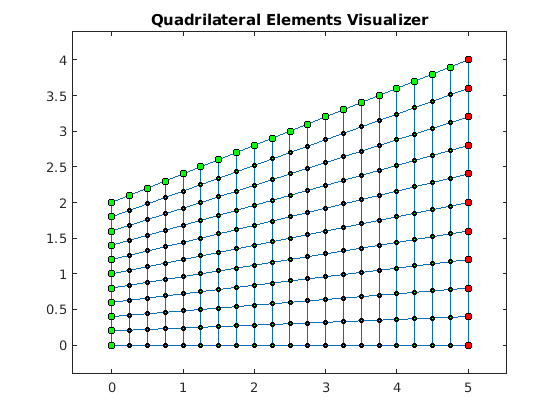

eval('meshAleta2DQuad')
numNod= size(nodes,1);
numElem= size(elem,1);

numbering=0;
plotElements(nodes, elem, numbering);

indTop=find(abs(2*nodes(:,1)/5 +2 - nodes(:,2))< 0.01);
%indTop= find(nodes(:,2)-2*nodes(:,1)/5 > 1.99); %top boundary's nodes' indices
indLeft=find(nodes(:,1) < 0.01);  %left boundary's nodes' indices
indRight=find(nodes(:,1) > 4.99); %right boundary's nodes' indices
%Id for the circle's nodes

hold on
plot(nodes(indTop,1),nodes(indTop,2),'o','color','black',...
    'markerFaceColor','green','markerSize',5)
plot(nodes(indLeft,1),nodes(indLeft,2),'o','color','black',...
    'markerFaceColor','green','markerSize',5)
plot(nodes(indRight,1),nodes(indRight,2),'o','color','black',...
    'markerFaceColor','red','markerSize',5)
hold off

Coefficients vector of model equation

a11=kc;
a12=0;
a21=a12;
a22=a11;
a00=0;
f=ff;
coeff=[a11,a12,a21,a22,a00,f];


Assemble the stiffness matrix

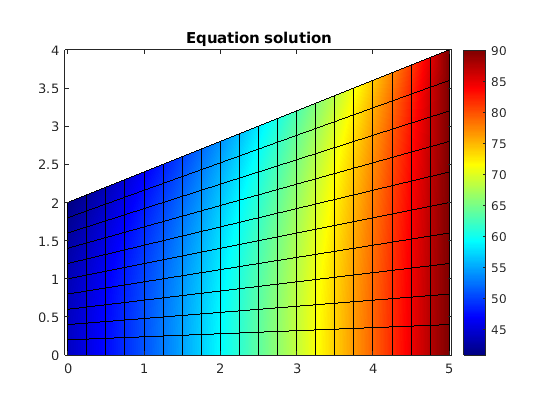

K=zeros(numNod);
F=zeros(numNod,1);
Q=zeros(numNod,1);

for e=1:numElem
    [Ke,Fe]=bilinearQuadElement(coeff,nodes,elem,e);
    %
    % Assemble the elements
    %
    rows=[elem(e,1); elem(e,2); elem(e,3); elem(e,4)];
    colums= rows;
    K(rows,colums)=K(rows,colums)+Ke; %assembly
    if (coeff(6) ~= 0)
        F(rows)=F(rows)+Fe;
    end
end %end for elements
%we save a copy of the initial F array
%for the postprocess step
Kini= K;
Fini= F;

%Boundary Conditions
fixedNodes= indRight'; %fixed Nodes (global numbering)
freeNodes= setdiff(1:numNod,fixedNodes); %free Nodes (global numbering)

%------------- Convetion BC
indCV=[indTop',indLeft']; %must be a row vector
indCV=unique(indCV);      %just to avoid duplicate indices
[K,Q]=applyConvQuad(indCV,beta,Tinf,K,Q,nodes,elem);

% ------------ Essential BC
u=zeros(numNod,1); %initialize uu vector
u(indRight)=tempRight;
Fm=F(freeNodes)-K(freeNodes,fixedNodes)*u(fixedNodes);%here u can be 
                                                      %different from zero 
                                                      %only for fixed nodes
%Reduced system
Km=K(freeNodes,freeNodes);
Fm=Fm+Q(freeNodes);

%Compute the solution
%solve the System
format short e; %just to a better view of the numbers
um=Km\Fm;
u(freeNodes)=um;
%u

%PostProcess: Compute secondary variables and plot results
Q=Kini*u-Fini;
titol='Equation solution';
colorScale='jet';
plotContourSolution(nodes,elem,u,titol,colorScale)

#### Write an excel file with the solutions (optional)

tableSol=[(1:numNod)',nodes,u,Q];
format short e
ts=table(int16(tableSol(:,1)),tableSol(:,2),tableSol(:,3),tableSol(:,4),...
    tableSol(:,5),'variableNames',{'NumNod','X','Y','T','Q'});
fileName='tempCoolingFinQuad.xlsx'; %Excel file's name
writetable(ts,fileName);
ts

ts = 231×5 table
    NumNod        X             Y             T              Q     
    ______    __________    __________    __________    ___________

       1      0.0000e+00    2.0000e+00    4.0807e+01    -6.8201e-01
       2      0.0000e+00    0.0000e+00    4.3985e+01    -3.0487e-01
       3      0.0000e+00    1.8000e+00    4.1485e+01    -5.8466e-01
       4      0.0000e+00    1.6000e+00    4.2047e+01    -5.9033e-01
       5      0.0000e+00    1.4000e+00    4.2522e+01    -5.9510e-01
       6      0.0000e+00    1.2000e+00    4.2922e+01    -5.9911e-01
       7      0.0000e+00    1.0000e+00    4.3254e+01    -6.0243e-01
       8      0.0000e+00    8.0000e-01    4.3520e+01    -6.0510e-01
       9      0.0000e+00    6.0000e-01    4.3725e+01    -6.0715e-01
      10      0.0000e+00    4.0000e-01    4.3869e+01    -6.0860e

#### Interpolated temperature at point p=[0.9,2.1]

%Compute the temperature at point p=[0.9,2.1].

for e = 1:numElem
    v1 = nodes(elem(e,1),:);
    v2 = nodes(elem(e,2),:);
    v3 = nodes(elem(e,3),:);
    v4 = nodes(elem(e,4),:);
    vertexs = [v1;v2;v3;v4];
    [alphas, isInside] = baryCoordQuad(vertexs, p);
    if isInside > 0
        numElemP = e;
        numNodsP = elem(numElemP,:);
        interpTempAtP = alphas * u(numNodsP);
        break;
    end
end

fmt = ['\nInterpolated temp.\n', ...
       'Point p = (%.2f,%.2f)\n',...   
       'Element Num: %4d\n',...
       'Nodes: %d, %d, %d, %d\n', ...
       'Temp.: %11.4e%cC\n'
      ];
fprintf(fmt,p,numElemP,numNodsP,interpTempAtP,char(0176))


Interpolated temp.
Point p = (0.90,2.10)
Element Num:   32
Nodes: 63, 82, 83, 64
Temp.:  4.6761e+01°C
